Betaski = 151;

% rdata = [[randn(40,2)+[-2 -1.5] zeros(40,1)];[randn(40,2)+[0 1.5] ones(40,1)];[randn(40,2)+[2 -1.5] ones(40,1)*2]]
% rdata_test = randn(40,2)*2
% 
% [Xnew,eVec,Dx,Sx] = flda(rdata(:,1:end-1),rdata(:,end));
% Xrnew = tlda(rdata_test,eVec)

% rdata = [[randn(20,1)+[-2] zeros(20,1)];[randn(20,1)+[2] ones(20,1)]]
% rdata_test = randn(20,1)
% 
% [clss,W] = flog(rdata(:,1:end-1),rdata(:,end))
% clss2 = tlog(rdata_test,W)

% rdata = [[randn(40,2)+[-2 -1.5] zeros(40,1)];[randn(40,2)+[0 1.5] ones(40,1)];[randn(40,2)+[2 -1.5] ones(40,1)*2]]
% rdata_test = randn(40,2)*2
% 
% clss = knnmdl(rdata(:,1:end-1),rdata(:,end),rdata_test)

% rdata = [[randn(40,2)+[-2 -1.5] zeros(40,1)];[randn(40,2)+[0 1.5] ones(40,1)];[randn(40,2)+[2 -1.5] ones(40,1)*2]]
% rdata_test = randn(40,2)
% 
% [Xr,clss] = fknn(rdata(:,1:end-1),rdata(:,end))
% [clsss] = tknn(Xr,rdata_test,clss)

% rdata = [[randn(40,2)+[-2 -1.5] zeros(40,1)];[randn(40,2)+[0 1.5] ones(40,1)];[randn(40,2)+[2 -1.5] ones(40,1)*2]]
% rdata_test = randn(40,2)
% 
% [pmax,cmax,mean,covariance,weight] = fnb_cont(rdata(:,1:end-1),rdata(:,end))
% [pmaxy,cmaxy] = tnb_cont(rdata_test,mean,covariance,weight)

% % [numdata] = cat2num(data,[1,4,5])
% % [catdata] = num2cat(data,[2,3])
% % [ohedata] = ohe(data,[1,4,5])

% data = readtable('C:\Users\agirb\OneDrive\Masaüstü\Harting\tennis.csv')
% 
% feats = [2,3];
% [catdata] = num2cat(data,feats)
% Xr = ["sunny" "3" "3" "FALSE"];
% [prob] = ftnb(catdata(:,1:end-1),catdata(:,end),Xr)

% data = readtable('C:\Users\agirb\OneDrive\Masaüstü\Harting\tennis.csv')
% 
% feats = [2,3];
% [catdata] = num2cat(data,feats)
% [prob] = fdt(catdata(:,1:end-1),catdata(:,end))

rdata = [[randn(40,2)+[-2 -1.5] zeros(40,1)];[randn(40,2)+[2 1.5] ones(40,1)]];
rdata_test = randn(20,2) * 2.5

rdata_test =     0.3458    0.1686
   -4.7677   -0.4678
   -0.9125    0.7293
   -2.1203    2.4692
   -1.9119    0.9823
   -2.8192    0.4864
    0.1955    0.6995
    5.2666    0.1281
   -1.7896   -1.9362
   -0.7013    1.9670



[hMargVecW, hMargVecB, hardMargin] = fsvm(rdata(:,1:end-1),rdata(:,end))

hMargVecW =     0.7242    0.6896


hMargVecB = 0.4020

hardMargin = 1.2188

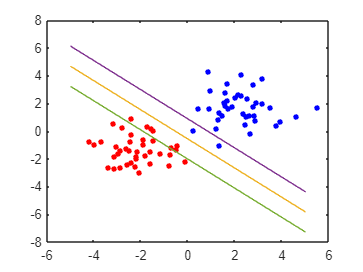

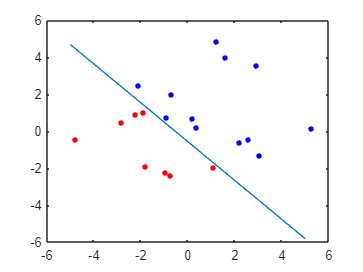

Clss = 20×1 logical array
   1
   0
   1
   1
   0
   0
   1
   1
   0
   1


[Clss] = tsvm(rdata_test,hMargVecW,hMargVecB)

function [Xnew] = cat2num(X,feats)
[row,col]= size(X(:,:));
Xnew = zeros(row,col);
for i = 1:col
    if sum(i == feats) > 0
        % [eh,~] = size(unique(X(:,i)));
        % Xcats = zeros(eh,1);
        [~,~,Xnew(:,i)] = unique(X(:,i));
    end
    if sum(i == feats) == 0
        Xnew(:,i) = table2array(X(:,i));
    end
end
end

% function [Xnew] = num2cat(X,feats)
% [row,col]= size(X(:,:));
% Xnew = zeros(row,col);
% for i = 1:col
%     if sum(i == feats) > 0
%         mean = table2array(X(:,i)).'*ones(row,1)/row;
%         std = cov(table2array(X(:,i)));
%         % N = @(x,mean,std,weight,n,c) (exp(-0.5 * (x(n,:)-mean(c,:)) * std^(-1) * (x(n,:)-mean(c,:)).')) / ((2 * pi)^(numCenter/2) * sqrt(abs(det(std)))); %weight(c,1)
%         borders = [mean-sqrt(std)*5/2; mean-sqrt(std)*3/2; mean-sqrt(std)/2; mean+sqrt(std)/2; mean+sqrt(std)*3/2; mean+sqrt(std)*5/2];
%         for j = 1:row
%             % Xnew(j,i) = sum(double(table2array(X(j,i)))>borders);
%             X{j,i} = sum(double(table2array(X(j,i)))>borders);
%         end
%     end
%     if sum(i == feats) == 0
%         % Xnew(:,i) = X(:,i);
%     end
% end
% Xnew = X
% end

function [Xnew] = num2cat(X,feats)
% X = data
% feats = [2,3]
[row,col]= size(X(:,:));
Xnew = zeros(row,col);
names = string(X.Properties.VariableNames);
temp = array2table(strings(row,col));
for i = 1:col
    if sum(i == feats) > 0
        mean = table2array(X(:,i)).'*ones(row,1)/row;
        std = cov(table2array(X(:,i)));
        % N = @(x,mean,std,weight,n,c) (exp(-0.5 * (x(n,:)-mean(c,:)) * std^(-1) * (x(n,:)-mean(c,:)).')) / ((2 * pi)^(numCenter/2) * sqrt(abs(det(std)))); %weight(c,1)
        borders = [mean-sqrt(std)*5/2; mean-sqrt(std)*3/2; mean-sqrt(std)/2; mean+sqrt(std)/2; mean+sqrt(std)*3/2; mean+sqrt(std)*5/2];
        for j = 1:row
            % Xnew(j,i) = sum(double(table2array(X(j,i)))>borders);
            X{j,i} = sum(double(table2array(X(j,i)))>borders);
        end
    end
    if sum(i == feats) == 0
    end
    temp(:,i).Variables = cellstr(string(X.(i)));
    temp = renamevars(temp,string(temp.Properties.VariableNames(i)),names(i));
end
Xnew = temp;
end

function [Xnew] = ohe(X,feats)
[row,col]= size(X(:,:));
Xnew = zeros(row,1);
for i = 1:col
    if sum(i == feats) > 0
        clear max
        lmt = ceil(log2(max(X(:,i))+1));
        ohedata = zeros(row,lmt);
        for j = 1:row
            ohedata(j,:) = dec2base(X(j,i),2,lmt) - '0';
        end
        Xnew = [Xnew ohedata];
    end
    if sum(i == feats) == 0
        Xnew = [Xnew X(:,i)];
    end
end
end

function [Xnew,eVec,Dx,Sx] = flda(X,Y)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
% Xr = rdata_test;
r = length(X(:,1));
c = length(X(1,:));
numClass = length(unique(Y));

% classların oranları
py = zeros(numClass,1);
for i = 1:numClass
    py(i,1) = sum(Y==i-1)/r; % class numarasına eşit olan çıktılar toplanıyor ve toplam çıktıya bölünüyor
end
pmax = max(py*r); % en kalabalık sınıfın mevcudunu veriyor

% train sınıf sayısına bölünüyor ve her bir parça en kalabalık sınıfa göre ayarlanıyor
pp = zeros(pmax,c,numClass); %sym('pp', [numClass 1]);
for i = 1:numClass
    pp(:,:,i) = [X(Y==i-1,:);zeros(pmax-py(i)*r,c)]; % her bir gruba o classın değerleri atılıyor ve kalan boşluk 0la dolduruluyor
end

% ortalama kovaryans ve ağırlık değerleri hesaplanıyoe
mean = zeros(numClass,c);
covariance = zeros(c,c,numClass);
weight = zeros(numClass,1);
for i = 1:numClass
    mean(i,:) = pp(:,:,i).'*ones(py(i)*r,1)/py(i)/r;
    covariance(:,:,i) = cov(pp(1:py(i)*r,:,i));
    weight(i,1) = py(i);
end
% tüm değerlerin ortalaması hesaplanıyor
meant = (X.'*ones(r,1)).'/r;

% (mj−m)(mj−m)^T
D = @(meant,mean,b) (meant-mean(b,:)).'*(meant-mean(b,:));
% (x−mj)(x−mj)^T
S = @(x,mean,a,b) (x(a,:,b)-mean(b,:)).'*(x(a,:,b)-mean(b,:));

Dx = zeros(c,c,numClass);
Sx = zeros(c,c,numClass);
for i = 1:numClass
    % nj * (mj−m)(mj−m)^T
    Dx(:,:,i) = D(meant,mean,i)  *  py(i)*r;
    for j = 1:py(i)*r
        % sums of (x−mj)(x−mj)^T
        Sx(:,:,i) = Sx(:,:,i) + S(pp,mean,j,i);
    end
end

Sb = sum(Dx,3); % Sb = D_c=1 + D_c=2 + D_c=3
Sw = sum(Sx,3); % Sw = S_c=1 + S_c=2 + S_c=3
[eVec,~] = eig(Sb,Sw); % from S_b*v=λ*S_w*v

Xnew = zeros(r,c);
for i = 1:r
    for j = 1:c
        % projection of X on eVec
        Xnew(i,j) = eVec(:,j).' * X(i,:).';
    end
end
end

function Xrnew = tlda(X,eVec)
r = length(X(:,1));
c = length(X(1,:));

Xrnew = zeros(r,c);
for i = 1:r
    for j = 1:c
        % projection of X on eVec
        Xrnew(i,j) = eVec(:,j).' * X(i,:).';
    end
end
end

function [clss,W] = flog(X,Y)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
itNumber = 200; 
r = length(X(:,1));
c = length(X(1,:));
numClass = length(unique(Y));

lambda = 0.01;
alpha = 0.01;
X1 =[ones(r,1) X];
W = (X1.'*X1 + lambda*eye(c+1))^(-1)*X1.'*Y; % init parameters
ypreds = zeros(r,1);
for q = 1:itNumber
    % likelyhood calculation
    for i=1:r
        ypreds(i) = 1/(1+exp(-(W.'*X1(i,:).'))); % p(X1(i,:).').';
    end
    ypreds(Y==0) = 1-ypreds(Y==0); % hedef 1 olduğu için 0a yaklaşması gerekenleri 1den çıkarıyoruz
    loglikelyhood = log(ypreds).'*ones(r,1);
    W = W - alpha*(loglikelyhood + lambda*W.^2); % parameter update
end

% elde ettiğimiz ağırlık matrisini uyguluyoruz
yw = zeros(r,1);
for i=1:r
    yw(i) = 1/(1+exp(-(W.'*X1(i,:).')));
end
clss = yw > 0.5;

% x = -5:0.1:5;
% y1 = zeros(101,1);
% for i=1:101
% y1(i)=1/(1+exp(-(W.'*[1;x(i)])));
% end
% plot(x,y1,'m-','MarkerSize',12)
% 
% hold on
% scatter(X,Y)
% 
% hold on
% yw = zeros(r,1);
% for i=1:r
%     yw(i) = 1/(1+exp(-(W.'*X1(i,:).')));
% end
% plot(X,yw,'g.','MarkerSize',12)
end

function clss = tlog(X,W)
itNumber = 200; 
r = length(X(:,1));
X1 =[ones(r,1) X];

% ağırlık matrisi uygulanıyor
yw = zeros(r,1);
for i=1:r
    yw(i) = 1/(1+exp(-(W.'*X1(i,:).')));
end
clss = yw > 0.5;

% x = -5:0.1:5;
% y1 = zeros(101,1);
% for i=1:101
% y1(i)=1/(1+exp(-(W.'*[1;x(i)])));
% end
% plot(x,y1,'m-','MarkerSize',12)
% 
% hold on
% scatter(X,Y)
% 
% hold on
% yw = zeros(r,1);
% for i=1:r
%     yw(i) = 1/(1+exp(-(W.'*X1(i,:).')));
% end
% plot(X,yw,'g.','MarkerSize',12)
end

function clss = knnmdl(X,Y,Xr)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
% Xr = rdata_test;
r = length(X(:,1)); % bağımsız train #satır
c = length(X(1,:)); % bağımsız train #kolon
rr = length(Xr(:,1)); % bağımsız test #satır
cr = length(Xr(1,:)); % bağımsız test #kolon
m = c;
k = 3; % k işte hani
numClass = length(unique(Y)); % sınıf sayısı

d = zeros(r,rr);
% her bir test gözleminin eğitim gözlemlerine uzaklıkları
for i = 1:rr
    for j = 1:r
        d(j,i) = sqrt(sum((Xr(i,:)-X(j,:)).^2));
    end
end

[~,i] = mink(d,k); % her bir test gözlemine en yakın (k) eğitim gözlemlerinin indexleri
G = Y(i).'; % en yakın üçünün sınıflarını alıyrouz
cls = zeros(rr,numClass);
for a = 1:rr
    for b = 1:numClass % (1,2,3) -> (0,1,2)
        cls(a,b) = sum(G(a,:)==b-1); % bu üçünden kaç tanesi hangi sınıfa yakın onu tutuyor
    end
end

[~,clss] = max(cls,[],2); % en fazla hangisinden var

figure;
plot(X(1:40,1),X(1:40,2),'r.','MarkerSize',12)
hold on
plot(X(41:80,1),X(41:80,2),'b.','MarkerSize',12)
hold on
plot(X(81:120,1),X(81:120,2),'k.','MarkerSize',12)
hold on
plot(Xr(clss==1,1),Xr(clss==1,2),'m.','MarkerSize',12)
hold on
plot(Xr(clss==2,1),Xr(clss==2,2),'c.','MarkerSize',12)
hold on
plot(Xr(clss==3,1),Xr(clss==3,2),'g.','MarkerSize',12)
%plot(mean(:,1),mean(:,2),'kx','MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Cluster 3',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

end

function [Xr,clss] = fknn(X,Y)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
r = length(X(:,1)); % bağımsız train #satır
c = length(X(1,:)); % bağımsız train #kolon
m = c;
k = 3; % k işte hani
numClass = length(unique(Y)); % sınıf sayısı
ch = 0.1; % çözünürlük

% i br çözünürlükte tüm harita bölünüyor
r1 = floor(min(X(:,1))):ch:ceil(max(X(:,1)));
c1 = floor(min(X(:,2))):ch:ceil(max(X(:,2)));

% her bir karo için nokta seçiliyor
Xr = zeros(length(r1)*length(c1),2);
kk = 0;
for i = r1
    for j = c1
        kk = kk + 1;
        Xr(kk,:) = [i j];
    end
end

rr = length(Xr(:,1)); % bağımsız test #satır
cr = length(Xr(1,:)); % bağımsız test #kolon

d = zeros(r,rr);
% her bir test gözleminin eğitim gözlemlerine uzaklıkları
for i = 1:rr
    for j = 1:r
        d(j,i) = sqrt(sum((Xr(i,:)-X(j,:)).^2));
    end
end

[~,i] = mink(d,k); % her bir test gözlemine en yakın (k) eğitim gözlemlerinin indexleri
G = Y(i).'; % en yakın üçünün sınıflarını alıyrouz
cls = zeros(rr,numClass);
for a = 1:rr
    for b = 1:numClass % (1,2,3) -> (0,1,2)
        cls(a,b) = sum(G(a,:)==b-1); % bu üçünden kaç tanesi hangi sınıfa yakın onu tutuyor
    end
end

[~,clss] = max(cls,[],2); % en fazla hangisinden var

figure;
plot(X(1:40,1),X(1:40,2),'r.','MarkerSize',12)
hold on
plot(X(41:80,1),X(41:80,2),'b.','MarkerSize',12)
hold on
plot(X(81:120,1),X(81:120,2),'k.','MarkerSize',12)
hold on
plot(Xr(clss==1,1),Xr(clss==1,2),'m.','MarkerSize',12)
hold on
plot(Xr(clss==2,1),Xr(clss==2,2),'c.','MarkerSize',12)
hold on
plot(Xr(clss==3,1),Xr(clss==3,2),'g.','MarkerSize',12)
%plot(mean(:,1),mean(:,2),'kx','MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Cluster 3',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off
end

function [clsss] = tknn(X,Xr,clss)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
% Xr = rdata_test;
r = length(X(:,1)); % bağımsız train #satır
c = length(X(1,:)); % bağımsız train #kolon
rr = length(Xr(:,1)); % bağımsız test #satır
cr = length(Xr(1,:)); % bağımsız test #kolon
m = c;
k = 1; % k işte hani
numClass = length(unique(clss)); % sınıf sayısı

d = zeros(r,rr);
% her bir test gözleminin eğitim gözlemlerine uzaklıkları
for i = 1:rr
    for j = 1:r
        d(j,i) = sqrt(sum((Xr(i,:)-X(j,:)).^2));
    end
end

[~,i] = mink(d,k); % her bir test gözlemine en yakın (k) eğitim gözlemlerinin indexleri
G = clss(i); % en yakın üçünün sınıflarını alıyrouz
cls = zeros(rr,numClass);
for a = 1:rr
    for b = 1:numClass % (1,2,3) -> (0,1,2)
        cls(a,b) = sum(G(a,:)==b); % bu üçünden kaç tanesi hangi sınıfa yakın onu tutuyor
    end
end

[~,clsss] = max(cls,[],2); % en fazla hangisinden var

figure;
plot(X(clss==1,1),X(clss==1,2),'r.','MarkerSize',12)
hold on
plot(X(clss==2,1),X(clss==2,2),'b.','MarkerSize',12)
hold on
plot(X(clss==3,1),X(clss==3,2),'k.','MarkerSize',12)
hold on
plot(Xr(clsss==1,1),Xr(clsss==1,2),'m.','MarkerSize',12)
hold on
plot(Xr(clsss==2,1),Xr(clsss==2,2),'c.','MarkerSize',12)
hold on
plot(Xr(clsss==3,1),Xr(clsss==3,2),'g.','MarkerSize',12)
%plot(mean(:,1),mean(:,2),'kx','MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Cluster 3',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off
end

function [pmax, cmax, mean, covariance, weight] = fnb_cont(X,Y)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);
% Xr = rdatay2;
r = length(X(:,1));
c = length(X(1,:));
m = c;
numClass = length(unique(Y));

% her grubun yüzdesi (ağırlığı) hesaplanıyor
weight = zeros(numClass,1);
for i = 1:numClass
    weight(i,1) = sum(Y==i-1)/r;
end

maxGroupSize = max(weight*r); % grupların büyüklüğünü tutuyor
pp = zeros(maxGroupSize,c,numClass); % veritabanı classlarına göre bölünüyor
for i = 1:numClass
    pp(:,:,i) = [X(Y==i-1,:);zeros(maxGroupSize-weight(i)*r,c)];
end

% ortalama, kovaryans hesaplanıyor
mean = zeros(c,numClass);
covariance = zeros(c,c,numClass);
for i = 1:numClass
    mean(:,i) = pp(:,:,i).'*ones(weight(i)*r,1)/weight(i)/r;
    covariance(:,:,i) = cov(pp(1:weight(i)*r,:,i));
end

% yoğunluk fonksiyonu
wN = @(x,mean,covariance,weight,n,c) (weight(c,1) * (exp(-0.5 * (x(n,:)-mean(:,c).') * covariance(:,:,c)^(-1) * (x(n,:)-mean(:,c).').')) / ((2 * weight(c,1))^(m/2) * sqrt(abs(det(covariance(:,:,c))))));

% y bilinen durumunda x gerçekleşme olasılığı
pxy = zeros(r,numClass);
for b = 1:numClass
    for a = 1:r
        pxy(a,b) = wN(X,mean,covariance,weight,a,b);
    end
end

% classın seçilme ihtimali
py = weight;
clear max
pyx = (pxy.'.*py).'; % naive bayes uygulanır
% BURADA px DENKLEME DAHİL EDİLMEZ

% sırasıyla maksimum pyx ve classı
[pmax, cmax] = max(pyx,[],2);
end

function [pmaxy, cmaxy] = tnb_cont(X,mean,covariance,weight)
r = length(X(:,1));
c = length(X(1,:));
m = c;
numClass = length(weight);

wN = @(x,mean,covariance,weight,n,c) (weight(c,1) * (exp(-0.5 * (x(n,:)-mean(:,c).') * covariance(:,:,c)^(-1) * (x(n,:)-mean(:,c).').')) / ((2 * weight(c,1))^(m/2) * sqrt(abs(det(covariance(:,:,c))))));

pxyy = zeros(r,numClass);
for b = 1:numClass
    for a = 1:r
        pxyy(a,b) = wN(X,mean,covariance,weight,a,b);
    end
end

pyy = weight;
clear max
pyxy = (pxyy.'.*pyy).';

[pmaxy, cmaxy] = max(pyxy,[],2);
end

function [prob] = ftnb(X,Y,Xr)
% X = catdata(:,1:end-1)
% Y = catdata(:,end)
% Xr = ["sunny" "3" "3" "FALSE"];
[row,col] = size(X(:,:));

% 
QQQ = 1;
indx = string(table2array(Y)) == "yes";
for i = 1:col
    if ~isnan(double(Xr(i)))
        QQQ = QQQ * sum(double(X.(i)).*indx == double(Xr(i))) / sum(indx);
    end
    if isnan(double(Xr(i)))
        QQQ = QQQ * sum(strcmp(X.(i),Xr(i)) .* indx) / sum(indx);
    end
end
QX = sum(indx)/row;

OOO = 1;
indx = string(table2array(Y)) == "no";
for i = 1:col
    if ~isnan(double(Xr(i)))
        OOO = OOO * sum(double(X.(i)).*indx == double(Xr(i))) / sum(indx);
    end
    if isnan(double(Xr(i)))
        OOO = OOO * sum(strcmp(X.(i),Xr(i)) .* indx) / sum(indx);
    end
end
OX = sum(indx)/row;

prob = QQQ * QX / (QQQ*QX + OOO*OX);
end

function [] = fdt(X,Y)
% X = catdata(:,1:end-1)
% Y = catdata(:,end)
[row,col] = size(X(:,:));

E = @(x) -x(:,1).*log2(x(:,1))-x(:,2).*log2(x(:,2));
ents = zeros(col,1);

for i = 1:col
    yo = string(X.(i));
    checkarr = unique(string(X.(i))).' == yo;
    indx = string(table2array(Y)) == "yes";
    ycheck = sum(unique(string(X.(i))).' == yo(indx));
    indx = string(table2array(Y)) == "no";
    ncheck = sum(unique(string(X.(i))).' == yo(indx));
    checker = [ycheck.' ncheck.']./sum([ycheck.' ncheck.'].').';
    checker(isnan(checker)) = 0;
    prob = sum(checkarr)/sum(sum(checkarr));
    prob(isnan(prob)) = 0;
    ent = E(checker);
    ent(isnan(ent)) = 0;
    ents(i,1) = prob*ent;
end
numY = [sum(ycheck) sum(ncheck)] / sum([sum(ycheck) sum(ncheck)]);
Gains = E(numY) - ents.';

% Burada ent==0 durumundaki tüm küme elemanları aynı çıktıyı veriyor
% ent==0 veren durum ağacın son dalıdır.
% ent==0 vermeyen durumlar için ayrı tablolar oluşturulup tüm edımlar tekrarlanır
% AMA NASIL YAPACAM BİLEMEDİM
% Ayrıca her bir olası güzergahın state equationa benzer denklemleri alınır

end

function [] = tdt(X,Y)
end

function [hMargVecW, hMargVecB, hardMargin] = fsvm(X,Y)
% X = rdata(:,1:end-1);
% Y = rdata(:,end);

hold off
plot(X(Y==0,1),X(Y==0,2),'r.','MarkerSize',12)
hold on
plot(X(Y==1,1),X(Y==1,2),'b.','MarkerSize',12)

alpha = [0:0.1:180].';
degress = [cos(alpha*pi/180) sqrt(1-cos(alpha*pi/180).^2)];

expressions = degress * X.';
row = length(expressions(:,1)); % sütun sayısı

margin = zeros(length(degress(:,1)),1);
for j = 1:length(degress(:,1))
    a = expressions(j,:).';

    e = zeros(2,1);
    e(1) = a(Y==0).'*ones(length(a(Y==0)),1)/length(a(Y==0));
    e(2) = a(Y==1).'*ones(length(a(Y==1)),1)/length(a(Y==1));
    
    clear max
    [~,emax] = max(e,[],1);
    clear min
    [~,emin] = min(e,[],1);
    
    clear max
    [bmax,~] = max(a(Y==emin-1),[],1);
    clear min
    [bmin,~] = min(a(Y==emax-1),[],1);
    
    margin(j,1) = bmin - bmax;
end

clear max
[~,qmax] = max(margin,[],1);
degress(qmax,:);

a = expressions(qmax,:).';

e = zeros(2,1);
e(1) = a(Y==0).'*ones(length(a(Y==0)),1)/length(a(Y==0));
e(2) = a(Y==1).'*ones(length(a(Y==1)),1)/length(a(Y==1));

clear max
[~,emax] = max(e,[],1);
clear min
[~,emin] = min(e,[],1);

clear max
[bmax,bxnum] = max(a(Y==emin-1),[],1);
clear min
[bmin,bnnum] = min(a(Y==emax-1),[],1);

f1 = X(Y==emin-1,:);
f2 = X(Y==emax-1,:);


p1 = f1(bxnum,:);
p2 = f2(bnnum,:);
p01 = bmax*degress(qmax,:);
p02 = bmin*degress(qmax,:);

% normvec = [degress(qmax,2) -degress(qmax,1)];
normvec = degress(qmax,:);
midpoint = (p01+p02)/2;
syms d real
prob = normvec * midpoint.' + d == 0; % merkezlerin ortasından geçen ve eğimini yukarıda bulduğumuz doğru dekleminin sabitine karar veriyoruz
d = double(solve(prob));

t = -5:0.1:5;
yt = -normvec(1)/normvec(2) * t - d/normvec(2);
hold on
plot(t,yt)

yt2 = -normvec(1)/normvec(2) * t - (d-1)/normvec(2);
hold on
plot(t,yt2)

yt3 = -normvec(1)/normvec(2) * t - (d+1)/normvec(2);
hold on
plot(t,yt3)

% degress(qmax,:)
% p1
% p01
% p2
% p02
% max(margin,[],1)
% hMargVecW = -normvec(1)/normvec(2);
% hMargVecB = -d/normvec(2);
hMargVecW = normvec;
hMargVecB = d;
hardMargin = max(margin,[],1);
end

function [Clss] = tsvm(X,hMargVecW,hMargVecB)
% X = rdata_test

projections = X * hMargVecW.' + hMargVecB;

Clss = projections >= 0;

t = -5:0.1:5;
yt = -hMargVecW(1)/hMargVecW(2) * t - hMargVecB/hMargVecW(2);

hold off
plot(t,yt)

hold on
plot(X(Clss==0,1),X(Clss==0,2),'r.','MarkerSize',12)
hold on
plot(X(Clss==1,1),X(Clss==1,2),'b.','MarkerSize',12)
end